# Taller 1 - No Paramétrica para Ciencia de los Datos

filename = 'Temperaturas.txt';
[Temperaturas,delimiterOut]=importdata(filename);

**Punto 1**

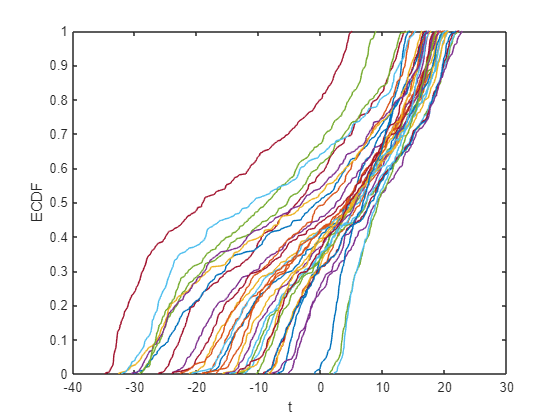

clf
figure(3)
for j = 1:35
    [F,t] = ecdf(Temperaturas(:,j));
    plot(t,F)
    hold on
end 
xlabel('t')
ylabel('ECDF')

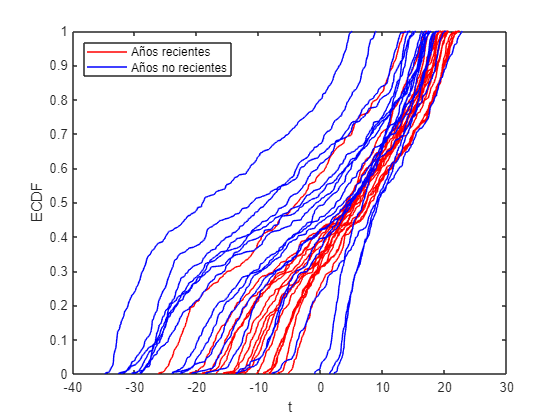

clf 
figure(4)
%plot años recientes
for j = 1:17
    [F1,t1] = ecdf(Temperaturas(:,j));
    plot(t1,F1, 'r','HandleVisibility', 'off')
    hold on
end 
%plot años no recientes
for j = 18:35
    [F2,t2] = ecdf(Temperaturas(:,j));
    plot(t2,F2, 'b','HandleVisibility', 'off')
    hold on
end 

plot(NaN, 'DisplayName', 'Años recientes', 'Color', 'r');
plot(NaN, 'DisplayName', 'Años no recientes', 'Color', 'b');

legend('Location','northwest')
xlabel('t')
ylabel('ECDF')

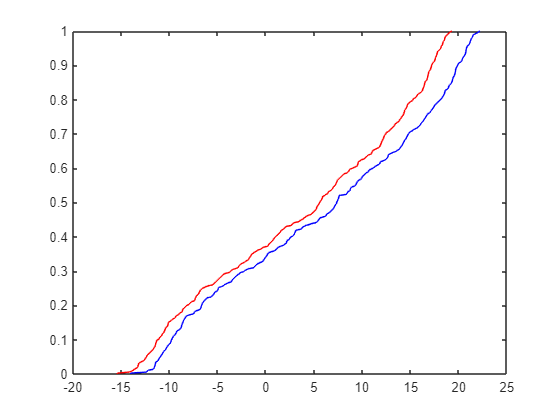

[a, b]= ecdf(Temperaturas(:,11));
[c,d]=  ecdf(Temperaturas(:,12));
clf 
figure(30)
plot(b,a, 'r')
hold on 
plot(d,c,'b')

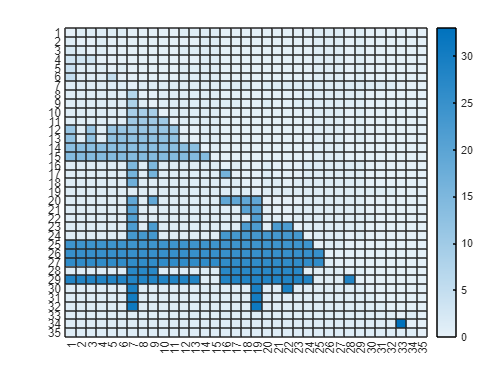

%Tabla de doble entrada con la media
medias= mean(Temperaturas,1);
m= zeros(35,35);

for i = 1:35
    valori = medias(i);
    for j = 1:35
        valorj = medias(j);
        if valori > valorj
            m(i,j) = 1;
            m(j,i)=0;
        end
        if valori < valorj
            m(j,i)=1;
            m(i,j)=0;
        end
        if valorj==valori
            m(i,j)=0.5;
            m(j,i)= 0.5;
        end
        if i==j
            m(i,j)=0;
        end
    end
end
clf
heatmap(m)

%Tabla de doble entrada segun la empirica 
m= zeros(35,35);

for i = 1:35
    [F1, t1]= ecdf(Temperaturas(:,i));
    areai= trapz(F1);
    for j = 1:35
        [F2,t2]= ecdf(Temperaturas(:,j));
        areaj= trapz(F2);
        if areai > areaj
            m(i,j) = 0;
            m(j,i)=1;
        end
        if areai < areaj
            m(i,j)=1;
            m(j,i)=0;
        end
        if areai == areaj
            m(i,j)=0.5;
            m(j,i)= 0.5;
        end
        if i==j
            m(i,j)=0;
        end
    end
end
clf 
heatmap(m)

**Punto 2**

media_est = zeros(35,1);


%Estimar media empírica
for i=1:35
    temps = Temperaturas(:,i);
    [F,t] = ecdf(temps);
    idx1 = t(find(t>=0));
    idx2 = t(find(t<0));
    Fq1 = F(find(t>=0));
    Fq2 = F(find(t<0));
    estimator = trapz(idx1,1-Fq1) - trapz(idx2,Fq2);
    media_est(i) = estimator;
end
hola=2
clf
plot(1:35, media_est,'color','k', 'DisplayName','Estimador')
hold on
plot(1:35, medias,'color','red','DisplayName','Media')
title("Estimator plug-in vs Media")
xlabel("Año")
ylabel("Temperatura media estimada")
legend('Location','southwest')

**Punto 3**

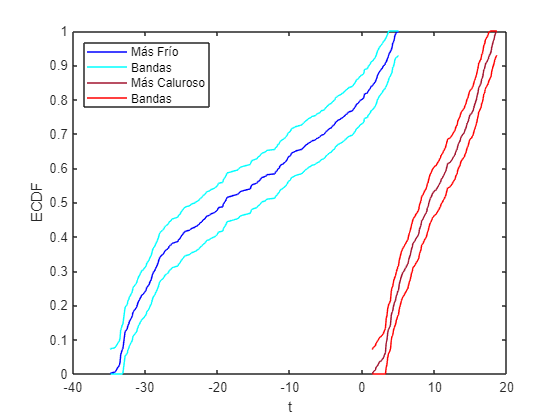

alpha= 0.05;
epsilon= sqrt(1/(2*length(Temperaturas))*log(2/alpha));

%minimo - bandas minimo 
medias= mean(Temperaturas,1);
[M, I]=min(medias);
[F, t]= ecdf(Temperaturas(:,I));
upper_band_min=zeros(length(F),1);lower_band_min=zeros(length(F),1);
for j= 1:length(F)
    upper_band_min(j)= min(F(j)+epsilon,1);
    lower_band_min(j) = max(F(j)-epsilon,0);
end


%maximo - bandas maximo
[M1, I1]= max(medias);
[F1, t1]= ecdf(Temperaturas(:,I1));
upper_band_max=zeros(length(F1),1);lower_band_max=zeros(length(F1),1);
for j= 1:length(F1)
    upper_band_max(j)= min(F1(j)+epsilon,1);
    lower_band_max(j) = max(F1(j)-epsilon,0);
end

clf 
figure(8)
%plotting coldest
plot(t,F, 'blue')
hold on 
plot(t,upper_band_min,'c')
hold on 
plot(t, lower_band_min,'c')

%plotting hotest
hold on 
plot(t1,F1,'color','#A2142F')
hold on 
plot(t1,upper_band_max,'r')
hold on 
plot(t1, lower_band_max,'r')
legend('Más Frío','Bandas','','Más Caluroso','Bandas','Location','northwest')
xlabel('t')
ylabel('ECDF')
hold off

**Punto 12**

medias= mean(Temperaturas,1);
[M, I]=min(medias);
tempMin= Temperaturas(:,I);
%bootstrap confidence interval estimation
b_max= bootstrp(1000,@max,tempMin);
max(tempMin);
CIB= [prctile(b_max,2.5) prctile(b_max,97.5)]

CIB =     4.6000    5.0000


% jackknife bias estimation
jk= jackknife(@max,tempMin);
n= length(tempMin);
jbias= (n-1)*(mean(jk)-max(tempMin))

jbias = -0.0997

%bootstrap variance estimation
vari=var(b_max)

vari = 0.0140

**Ejercicio 3 - Página 24**

%con distribución normal
alpha= 0.05;
N=1000;
m=100;
epsilon= sqrt((1/(2*m))*log(2/alpha));
conts= zeros(N,1);
for j= 1:N
    norm = normrnd(0,1,m,1);
    [F, t]= ecdf(norm);
    upper_band=zeros(length(F),1);lower_band=zeros(length(F),1);

    for i = 1:length(F)
        upper_band(i)= min(F(i)+epsilon,1);
        lower_band(i)= max(F(i)-epsilon,0);
    end

    cont=0;
    teor= zeros(length(t),1);
    for k= 1:length(t)
        teorical= normcdf(t(k));
        teor(k)= teorical;
        if (lower_band(k) <= teorical) && (teorical <= upper_band(k))
            cont= cont +0;
        else 
            cont= cont+1;
        end
    end

    if cont ==0
        conts(j)= 1;
    end
end
porcentaje= (sum(conts)/N)*100

porcentaje = 96.1000

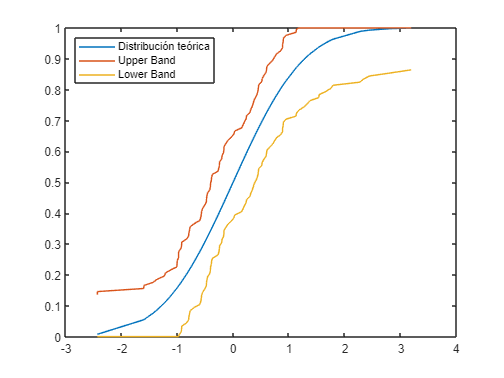

clf
plot(t,teor,'DisplayName','Distribución teórica')
hold on
plot(t, upper_band,'DisplayName','Upper Band')
hold on 
plot(t, lower_band,'DisplayName','Lower Band')
legend('Location','northwest')

%con distribución couchy 
alpha= 0.05;
N=1000;
m=100;
epsilon= sqrt((1/(2*m))*log(2/alpha));
conts= zeros(N,1);
for j= 1:N
    couch = trnd(1,m,1);
    [F, t]= ecdf(couch);
    upper_band=zeros(length(F),1);lower_band=zeros(length(F),1);

    for i = 1:length(F)
        upper_band(i)= min(F(i)+epsilon,1);
        lower_band(i)= max(F(i)-epsilon,0);
    end

    cont=0;
    teor= zeros(length(t),1);
    for k= 1:length(t)
        teorical= tcdf(t(k),1);
        teor(k)= teorical;
        if (lower_band(k) <= teorical) && (teorical <= upper_band(k))
            cont= cont +0;
        else 
            cont= cont+1;
        end
    end

    if cont ==0
        conts(j)= 1;
    end
end
porcentaje= (sum(conts)/N)*100

porcentaje = 96.9000

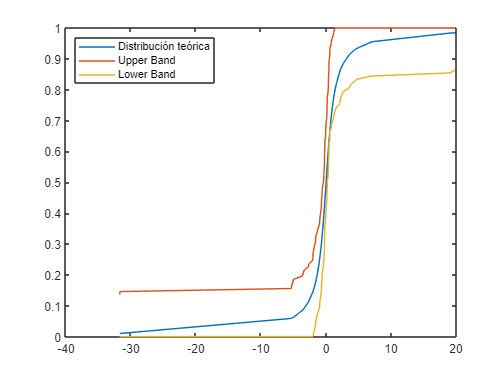

clf
plot(t,teor,'DisplayName','Distribución teórica')
hold on
plot(t, upper_band,'DisplayName','Upper Band')
hold on 
plot(t, lower_band,'DisplayName','Lower Band')
legend('Location','northwest')